## **Punto 1**

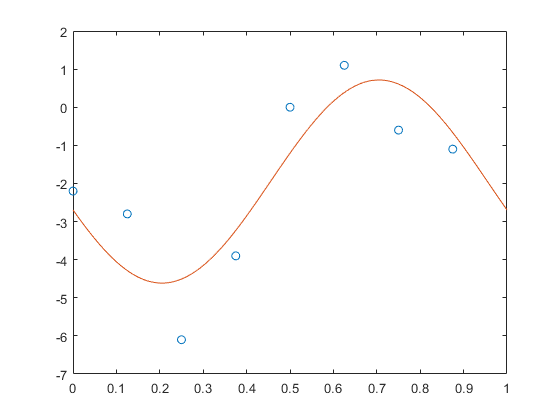

t = [0; 1/8; 1/4; 3/8; 1/2; 5/8; 3/4; 7/8];
y = [-2.2; -2.8; -6.1; -3.9; 0.0; 1.1; -0.6; -1.1];

A = [ones(8,1), cos(2*pi*t(:,1)), sin(2*pi*t(:,1))];

A_ = A'*A;
B_ = A'*y;
sol = A_\B_;
proy = A*sol;
t_ = 0:0.01:1;
w = sol(1)+sol(2)*cos(2*pi*t_)+sol(3)*sin(2*pi*t_);
plot(t,y,'o',t_,w);


y1 = sol(1)+sol(2)*cos(2*pi*t)+sol(3)*sin(2*pi*t);
R = abs(y1 - y);
n2 = norm(R, 2);

## Punto 2

### Modelo ${y\;=\;c}_1 *{\left(c_2 \right)}^x$

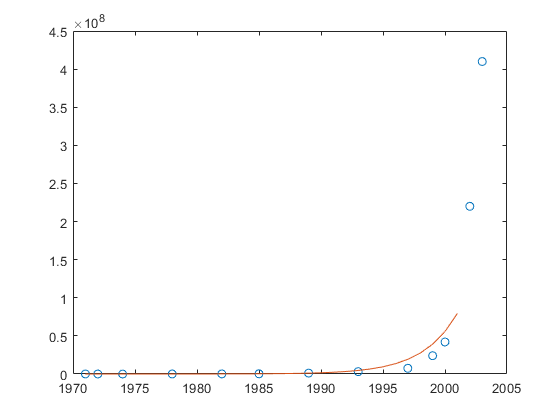

year = [1971; 1972; 1974; 1978; 1982; 1985; 1989; 1993; 1997; 1999; 2000; 2002; 2003];
transistors = [2250;2500;5000;29000;120000;275000;1180000;3100000;7500000;24000000;42000000;220000000;410000000];

A = [ones(13,1), year];
A_ = A'*A; 
B_ = A'*log(transistors);
sol = A_\B_;

t_ = 1971:1:2003;
w = exp(sol(1)) * (exp(sol(2)).^t_);
plot(year,transistors,'o',t_,w);


%Residuo
R = exp(sol(1)) * (exp(sol(2)).^ year) - transistors;
n2 = norm(R, 2)

n2 = Inf

### Modelo $y=c_1 \;{*\;e}^{c_2 x}$

year = [1971; 1972; 1974; 1978; 1982; 1985; 1989; 1993; 1997; 1999; 2000; 2002; 2003];
transistors = [2250;2500;5000;29000;120000;275000;1180000;3100000;7500000;24000000;42000000;220000000;410000000];

A = [ones(13,1), year];
A_ = A'*A; 
B_ = A'*log(transistors);
sol = A_\B_;

t_ = 1971:1:2003;
w = exp(sol(1)) * exp(sol(2)*t_);
plot(year,transistors,'o',t_,w)


%Residuo
R = exp(sol(1)) * exp(sol(2)*t_) - transistors;
n2_ = norm(R, 2)

n2_ = Inf

## Punto 3

x = 2:0.2:4;
y = zeros(11, 1);
for i=1:11
    s = 1;
    for j=1:7
        s = s + x(i)^j;
    end
    y(i) = s;
end
p = (0:7);
A = x'.^p;
A_ = A'*A;
B_ = A'*y;
sol = A_\B_;

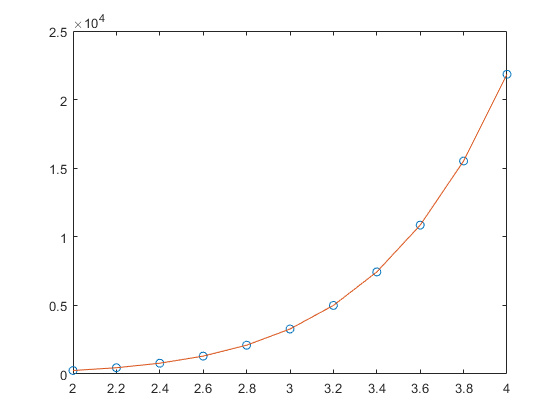

plot(x,y,'o', x, (x'.^p)*sol)

## Punto 3 con QR economico

[Q, R] = qr(A, 0);
ans = R\(Q'*y);